# Gyroscope data for Yaw and Pitch in R12 Trial 1

SI-000742 for S5

SI-000764 for S6

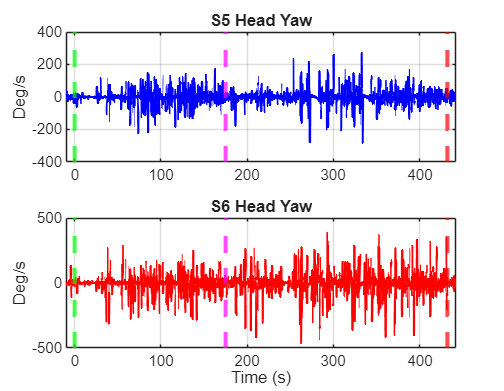

%% 1. SETUP & LOAD BOTH SENSORS
h5_file = 'C:\Users\jvela\Downloads\BGBMB - Rehearsal 12 (4 Jul, 2024)\BGBMB - Rehearsal 12 (4 Jul, 2024)\20240704_R12_Motion2.h5';

% Define Sensor IDs
id_s5 = 'SI-000742';
id_s6 = 'SI-000764';

% Load Time (Assume synchronized, using S6 timebase)
t_micro = h5read(h5_file, ['/' id_s6 '/Time']);      
t_sec = double(t_micro) / 1e6;             
t_plot = t_sec - t_sec(1);

% --- Helper Function to Load & Process ---
function [yaw, pitch, acc_mag] = get_sensor_data(h5_file, sensor_id, fs)
    % Paths
    p_gyro = ['/' sensor_id '/Calibrated/Gyroscopes'];
    p_acc  = ['/' sensor_id '/Calibrated/Accelerometers'];
    
    % Load Gyro & Accel
    g_raw = h5read(h5_file, p_gyro).';
    a_raw = h5read(h5_file, p_acc).';
    
    % Filter Gyro
    g_deg = rad2deg(g_raw);
    [b,a] = butter(2, 0.1/(fs/2), 'high');
    g_clean = filtfilt(b, a, g_deg);
    
    % Extract
    pitch = g_clean(:, 1); % X-axis
    yaw   = g_clean(:, 3); % Z-axis
    
    % Accel Magnitude
    acc_mag = sqrt(a_raw(:,1).^2 + a_raw(:,2).^2 + a_raw(:,3).^2);
end

% Load Data for S5 and S6
fs_imu = 128;
[yaw_s5, pitch_s5, acc_s5] = get_sensor_data(h5_file, id_s5, fs_imu);
[yaw_s6, pitch_s6, acc_s6] = get_sensor_data(h5_file, id_s6, fs_imu);


%% 2. SLICING & VIEW WINDOW
% Define Events (Indices)
idx_event_start = 143951; 
idx_event_trans = 166351;
idx_event_end   = 199247;

% Define View Window (Pad 10s)
pad_sec = 10; 
pad_samp = round(pad_sec * fs_imu);
idx_view_start = max(1, idx_event_start - pad_samp);
idx_view_end   = min(length(t_plot), idx_event_end + pad_samp);

% Slice Data S5
y5_cut = yaw_s5(idx_view_start:idx_view_end);
p5_cut = pitch_s5(idx_view_start:idx_view_end);
a5_cut = acc_s5(idx_view_start:idx_view_end);

% Slice Data S6
y6_cut = yaw_s6(idx_view_start:idx_view_end);
p6_cut = pitch_s6(idx_view_start:idx_view_end);
a6_cut = acc_s6(idx_view_start:idx_view_end);

% Time Axis (0 = Dance Start)
t_view = t_plot(idx_view_start:idx_view_end);
t_zero = t_plot(idx_event_start);
t_rel  = t_view - t_zero;

% Line Positions
t_l_start = 0;
t_l_trans = t_plot(idx_event_trans) - t_zero;
t_l_end   = t_plot(idx_event_end)   - t_zero;


%% FIGURE 1: COMPARATIVE YAW (Horizontal)
figure('Name', 'Comparative Yaw (S5 vs S6)', 'Color', 'w', 'Position', [100 100 900 700]);

% S5 Yaw
subplot(2,1,1);
plot(t_rel, y5_cut, 'b', 'LineWidth', 1.2);
title('S5 Head Yaw'); ylabel('Deg/s'); grid on; xlim([t_rel(1) t_rel(end)]);
xline(t_l_start, 'g--', 'LineWidth', 2);
xline(t_l_trans, 'm--', 'LineWidth', 2);
xline(t_l_end,   'r--', 'LineWidth', 2);

% S6 Yaw
subplot(2,1,2);
plot(t_rel, y6_cut, 'r', 'LineWidth', 1.2);
title('S6 Head Yaw'); ylabel('Deg/s'); grid on; xlim([t_rel(1) t_rel(end)]);
xlabel('Time (s)');
xline(t_l_start, 'g--', 'LineWidth', 2);
xline(t_l_trans, 'm--', 'LineWidth', 2);
xline(t_l_end,   'r--', 'LineWidth', 2);

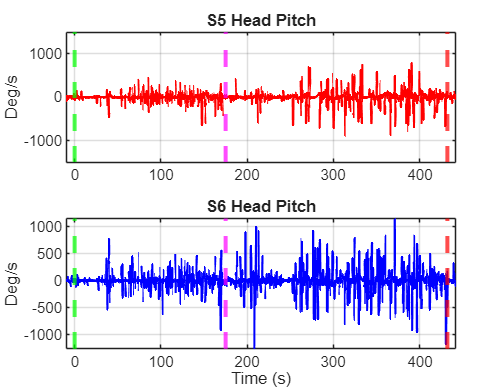



%% FIGURE 2: COMPARATIVE PITCH (Vertical)
figure('Name', 'Comparative Pitch (S5 vs S6)', 'Color', 'w', 'Position', [150 150 900 700]);

% S5 Pitch
subplot(2,1,1);
plot(t_rel, p5_cut, 'r', 'LineWidth', 1.2);
title('S5 Head Pitch'); ylabel('Deg/s'); grid on; xlim([t_rel(1) t_rel(end)]);
xline(t_l_start, 'g--', 'LineWidth', 2);
xline(t_l_trans, 'm--', 'LineWidth', 2);
xline(t_l_end,   'r--', 'LineWidth', 2);
y_limits = [-1500 1500];
ylim(y_limits);

% S6 Pitch
subplot(2,1,2);
plot(t_rel, p6_cut, 'b', 'LineWidth', 1.2);
title('S6 Head Pitch'); ylabel('Deg/s'); grid on; xlim([t_rel(1) t_rel(end)]);
xlabel('Time (s)');
xline(t_l_start, 'g--', 'LineWidth', 2);
xline(t_l_trans, 'm--', 'LineWidth', 2);
xline(t_l_end,   'r--', 'LineWidth', 2);

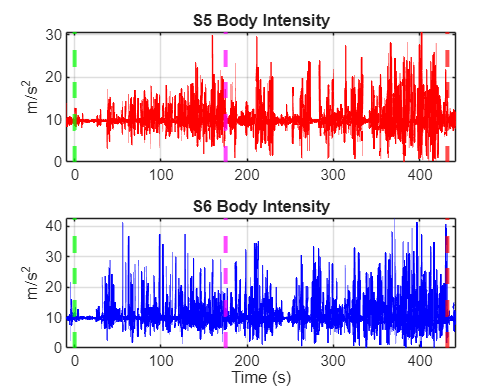



%% FIGURE 3: COMPARATIVE INTENSITY (Accelerometer)
figure('Name', 'Comparative Intensity (S5 vs S6)', 'Color', 'w', 'Position', [200 200 900 700]);

% S5 Intensity
subplot(2,1,1);
plot(t_rel, a5_cut, 'r', 'LineWidth', 1);
title('S5 Body Intensity'); ylabel('m/s^2'); grid on; xlim([t_rel(1) t_rel(end)]);
xline(t_l_start, 'g--', 'LineWidth', 2);
xline(t_l_trans, 'm--', 'LineWidth', 2);
xline(t_l_end,   'r--', 'LineWidth', 2);

% S6 Intensity
subplot(2,1,2);
plot(t_rel, a6_cut, 'b', 'LineWidth', 1);
title('S6 Body Intensity'); ylabel('m/s^2'); grid on; xlim([t_rel(1) t_rel(end)]);
xlabel('Time (s)');
xline(t_l_start, 'g--', 'LineWidth', 2);
xline(t_l_trans, 'm--', 'LineWidth', 2);
xline(t_l_end,   'r--', 'LineWidth', 2);

Slice

Continue

%% VISUALIZATION: ZOOMED FILTER QUALITY CHECK
% Define the zoom window (e.g., 10 seconds of data)
zoom_start = 90; 
zoom_end   = 100; 
y_limits = [-320 320];

% Find indices for this time window
idx_zoom = t_cut_rel >= zoom_start & t_cut_rel <= zoom_end;

Unrecognized function or variable 't_cut_rel'.


figure('Name', 'Filter Quality Check (Zoomed)', 'Color', 'w', 'Position', [150 150 800 600]);
tiledlayout(2,1, 'TileSpacing', 'compact', 'Padding', 'compact');

% 1. Zoomed Yaw (Horizontal)
nexttile;
plot(t_cut_rel(idx_zoom), gyro_deg_cut(idx_zoom, 3), 'Color', [0.7 0.7 0.7], 'LineWidth', 1.5); hold on;
plot(t_cut_rel(idx_zoom), yaw_cut(idx_zoom), 'b', 'LineWidth', 1.5);

title(sprintf('Yaw (%.0fs - %.0fs)', zoom_start, zoom_end));
legend('Raw', 'Cleaned', 'Location', 'best');
ylabel('Deg/s'); 
grid on;
xlim([zoom_start zoom_end]); 
ylim(y_limits);

% 2. Zoomed Pitch (Vertical)
nexttile;
plot(t_cut_rel(idx_zoom), gyro_deg_cut(idx_zoom, 1), 'Color', [0.7 0.7 0.7], 'LineWidth', 1.5); hold on;
plot(t_cut_rel(idx_zoom), pitch_cut(idx_zoom), 'r', 'LineWidth', 1.5);

title(sprintf('Pitch (%.0fs - %.0fs)', zoom_start, zoom_end));
xlabel('Time (s)'); ylabel('Deg/s');
grid on;
xlim([zoom_start zoom_end]); 
ylim(y_limits);

n

%% VISUALIZATION: PROFESSIONAL OVERVIEW + ZOOM
figure('Name', 'S5 vs S6 Pitch: Overview & Detail', 'Color', 'w', 'Position', [50 50 1000 800]);
t = tiledlayout(3, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

% --- DEFINITIONS ---
% Select interesting Zoom Windows (Change these to match your data!)
zoom1_range = [290 305]; % Example: Intense Section (15s)
zoom2_range = [150 165]; % Example: Transition/Quiet Section (15s)

% --- ROW 1: FULL OVERVIEW (Spanning both columns) ---
ax_main = nexttile([1 2]); % Span 2 columns
plot(t_rel, p5_cut, 'r', 'LineWidth', 0.5); hold on; % Thinner line for density
plot(t_rel, p6_cut, 'b', 'LineWidth', 0.5); 

% Add Event Lines
xline(0, 'g--', '', 'LabelVerticalAlignment', 'bottom', 'LineWidth', 1.5);
xline(t_l_trans, 'm--', '', 'LabelVerticalAlignment', 'bottom', 'LineWidth', 1.5);
xline(t_l_end, 'r--', '', 'LabelVerticalAlignment', 'bottom', 'LineWidth', 1.5);

% Highlight the Zoom Regions with transparent boxes
xregion(zoom1_range(1), zoom1_range(2), 'FaceColor', [0.2 0.2 0.2], 'FaceAlpha', 0.1);
xregion(zoom2_range(1), zoom2_range(2), 'FaceColor', [0.2 0.2 0.2], 'FaceAlpha', 0.1);

title('Head Pitch S5 vs S6');
ylabel('Deg/s'); xlim([t_rel(1) t_rel(end)]);
legend('S5', 'S6', 'Location', 'northeast');
grid on; set(gca, 'GridAlpha', 0.3); % Subtle grid

% --- ROW 2: ZOOM 1 (Transition / Quiet) ---
% S5 Zoom 1
nexttile;
idx_z1 = t_rel >= zoom2_range(1) & t_rel <= zoom2_range(2);
plot(t_rel(idx_z1), p5_cut(idx_z1), 'r', 'LineWidth', 1.5); hold on;
plot(t_rel(idx_z1), p6_cut(idx_z1), 'b', 'LineWidth', 1.5);
title('Zoomed Window A');
xlabel('Time (s)'); ylabel('Deg/s'); ylim([-650 600]);xlim(zoom2_range); grid on;

% --- ROW 3: ZOOM 2 (High Intensity) ---
% S5 Zoom 2
nexttile; % Place next to it or below
idx_z2 = t_rel >= zoom1_range(1) & t_rel <= zoom1_range(2);
plot(t_rel(idx_z2), p5_cut(idx_z2), 'r', 'LineWidth', 1.5); hold on;
plot(t_rel(idx_z2), p6_cut(idx_z2), 'b', 'LineWidth', 1.5);
title('Zoomed Window B');
xlabel('Time (s)'); ylabel('Deg/s'); xlim(zoom1_range); grid on;

% (Optional Layout Adjustment: You can arrange these side-by-side or
% stacked)s